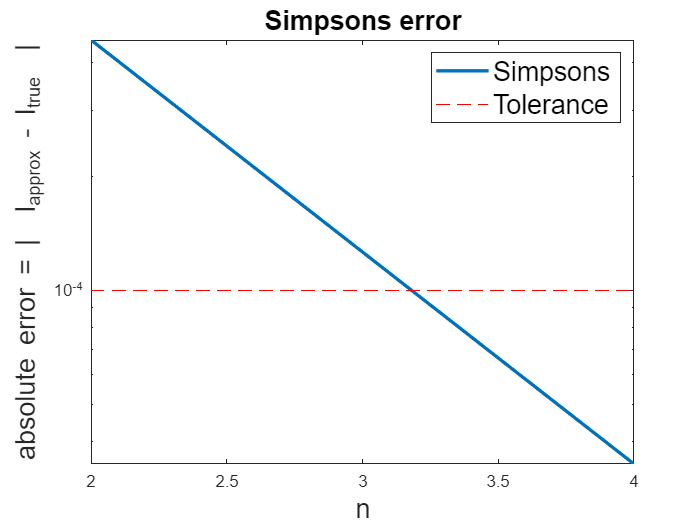

f = @(x) log(2. * x);
a = 1;
b = 2;
true_Solution = (4 * log(4) - 2 * log(2) - 2) / 2;

Tol = 10^(-4);
n = 1;
err_abs_simp = Inf;
n_vals_simp = [];
itr = 0;
while err_abs_simp > Tol
    itr = itr + 1;
    n = n*2;
    n_vals_simp(itr) = n;
    I = Simpson(f, a, b, n);
    err_abs_simp(itr) = abs(true_Solution - I);
end
figure
semilogy(n_vals_simp, err_abs_simp, 'LineWidth',2);
hold on;
semilogy([min(n_vals_simp(1)), max(n_vals_simp(end))], [Tol, Tol], 'r--');
legend('Simpsons','Tolerance','FontSize',16);
title('Simpsons error','FontSize',16)
xlabel('n','FontSize',16);
ylabel('absolute error = |  I_{approx} - I_{true}  |','FontSize',16);